# Understand the fundamentals of EMG signal pre-processing.

clc;
clear all;
close all;

% Load the struct from ES1_emg.mat file
load("ES1_emg.mat"); 

% Extract the data 
data = Es1_emg.matrix;
Deltoid_emg = data(:, 1);
Deltoid_AccX = data(:, 2);
Deltoid_AccY = data(:, 3);
Deltoid_AccZ = data(:, 4);

***Filter the Signal with a BPF***

% Define sampling frequency and time vector
fs = 2000; 
N = length(Deltoid_emg);
t = (0:(N - 1)) / fs; 

% Define the filter parameters
low_cutoff = 30;  % Lower cutoff frequency (Hz)
high_cutoff = 450;  % Higher cutoff frequency (Hz)
nyquist_freq = fs / 2;  % Nyquist frequency

% Design the bandpass FIR filter using the 'fir1' function
filter_order = 100;  % Adjust the filter order as needed
filter_coefficients = fir1(filter_order, [low_cutoff/nyquist_freq, high_cutoff/nyquist_freq], 'band');

% Apply the filter to the EMG signal using 'filtfilt'
filtered_emg = filtfilt(filter_coefficients, 1, Deltoid_emg);

***Rectify the Signal***

% Apply full-wave rectification to the filtered EMG signal
rectified_emg = abs(filtered_emg);

***Compute the Envelope***

% Define the filter parameters for the low-pass filter
lowpass_cutoff = 5;  % Frequency cutoff for low-pass filter (Hz)

% Design the low-pass FIR filter using the 'fir1' function
lowpass_filter_order = 100;  % Adjust the filter order as needed
lowpass_filter_coefficients = fir1(lowpass_filter_order, lowpass_cutoff/nyquist_freq, 'low');

% Apply the low-pass filter to the rectified EMG signal
envelope_emg = filtfilt(lowpass_filter_coefficients, 1, rectified_emg);

***Downsampling***

% Define the downsampling factor
downsampling_factor = 4;  % Adjust the factor as needed

% Downsample the envelope signal
downsampled_emg = downsample(envelope_emg, downsampling_factor);

% Create a new time vector for the downsampled signal
t_downsampled = downsample(t, downsampling_factor);

***Plots***

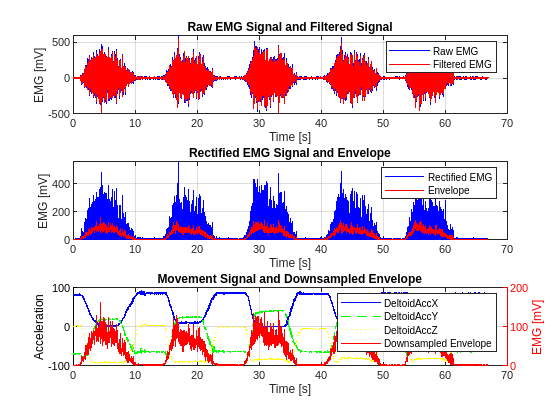

figure;

% Plot 1: Original EMG signal overlaid with the filtered signal
subplot(3,1,1);
plot(t, Deltoid_emg, 'b', 'LineWidth', 1);
hold on;
plot(t, filtered_emg, 'r', 'LineWidth', 1);
title('Raw EMG Signal and Filtered Signal');
xlabel('Time [s]');
ylabel('EMG [mV]');
legend('Raw EMG', 'Filtered EMG');
grid on;

% Plot 2: Rectified EMG signal overlaid with the envelope
subplot(3,1,2);
plot(t, rectified_emg, 'b', 'LineWidth', 1);
hold on;
plot(t, envelope_emg, 'r', 'LineWidth', 1);
title('Rectified EMG Signal and Envelope');
xlabel('Time [s]');
ylabel('EMG [mV]');
legend('Rectified EMG', 'Envelope');
grid on;

% Plot 3: Movement signal overlaid with the downsampled envelope
subplot(3,1,3);
ax = gca;
yyaxis left
plot(t, 100*Deltoid_AccX, 'b', 'LineWidth', 1); 
% Boh, il *100 l'ho tirato fuori dal culo sennò non si vedevano i segnali
hold on;
plot(t, 100*Deltoid_AccY, 'g', 'LineWidth', 1);
hold on;
plot(t, 100*Deltoid_AccZ, 'y', 'LineWidth', 1);
hold on;
yyaxis right
ax.YColor = 'r';
plot(t_downsampled, downsampled_emg, 'r', 'LineWidth', 1);
title('Movement Signal and Downsampled Envelope');
xlabel('Time [s]');
ylabel('EMG [mV]','Color','r');
yyaxis left
ylabel('Acceleration','Color','k');
legend('DeltoidAccX', 'DeltoidAccY', 'DeltoidAccZ', 'Downsampled Envelope');
ax.YColor = 'k';
grid on;

`Answer to Question A:`` Down-sampling is performed after envelope computation to reduce data size and processing requirements. Enveloping smoothes out the signal and reduces the impact of high-frequency noise, making it suitable for further down-sampling without significant loss of information.`

`Answer to Question B:`` In the graph 'Movement Signal and Downsampled Envelope' we have amplified the acceleration values by a factor of 100, because otherwise we weren't able to compare the two different range values.`

`Looking at this graph, in particular 'Downsampled Envelope' (red line) and 'DeltoidAccY' (green line) signals, we notice that there is a slight delay between the activation of the EMG signal and the movement: this delay consists in a preparation phase of the muscle to the activation of movement, and its absence is the cause of diseases and dysfunctions.`